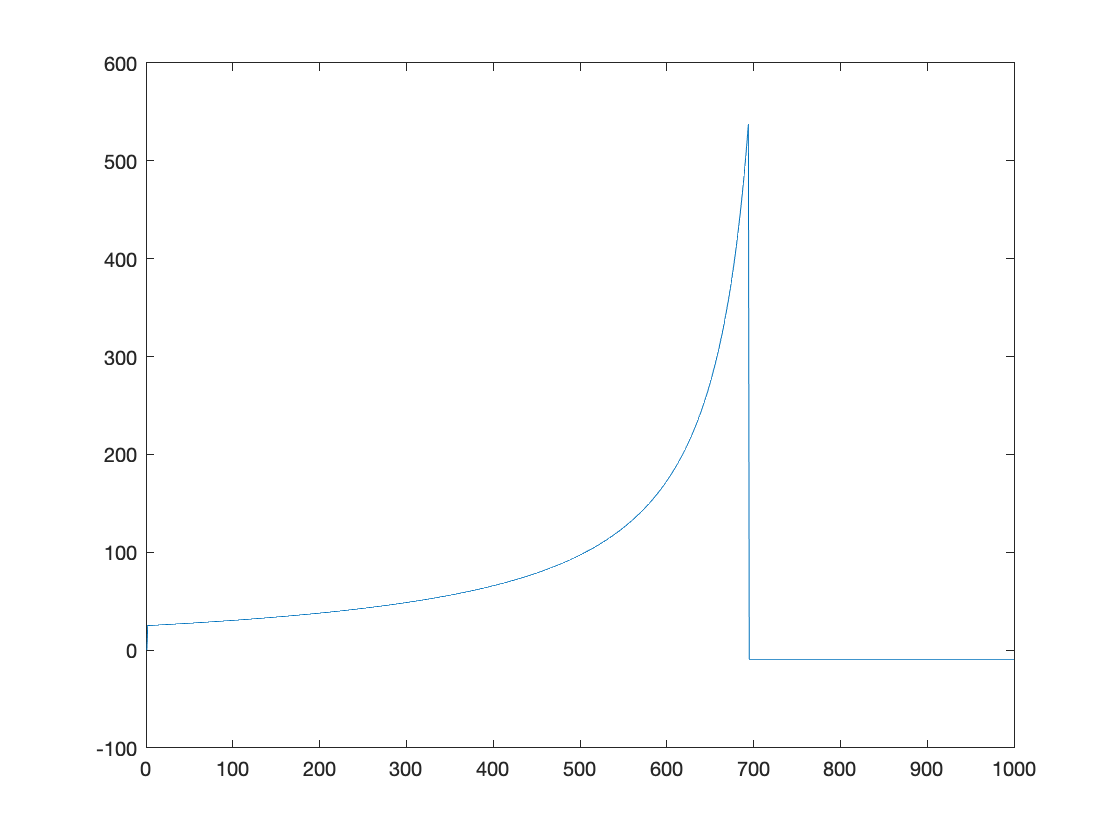

clear

%Time Conditions
time_step = 1;
time_end = 1000;

% fuel = 2723900;
%Variables
mass_empty = 185300;
mass_full = 2909200;
mass_burn = 3930.6; 
mass_burn_complete = 0; 
gravity_c = 3.721;
exhaust_velocity = 2.58e4;

% Arrays
t = 1:time_step:time_end;

acceleration = zeros(1,length(t));
acceleration(1) = 0;

velocity = zeros(1,length(t));
velocity(1) = 0;

position = zeros(1,length(t));
position(1) = 0;

mass_change(1) = mass_full;

for i = 2:length(t)

    if mass_change(i-1) > mass_empty
        dmdt = mass_burn;
    else
        dmdt = mass_burn_complete;
    end

    mass_change(i) = mass_change(i-1) - time_step*dmdt;

    acceleration(i) = exhaust_velocity/mass_change(i)*dmdt-gravity_c;
 


end

plot(t,acceleration)

xlim([0 1000])
ylim([-100 600])